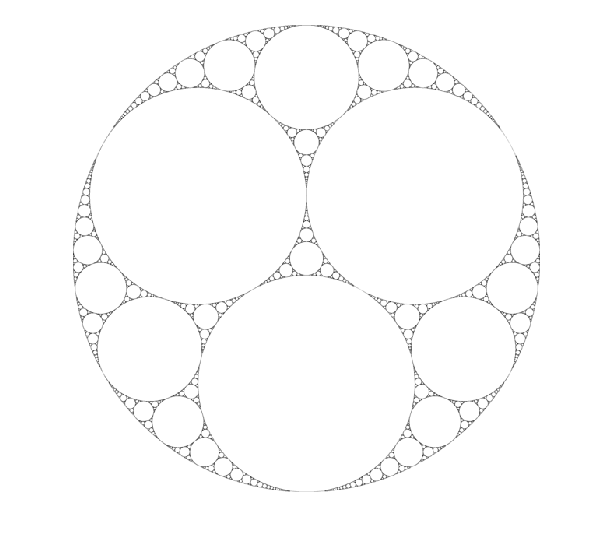

% P = "test_img/pepper.ascii.pgm";
P = "test_img/apollonian_gasket.ascii.pgm";
Test_Image = imread(fullfile(P));
% P = "test_img/Image.txt"
% Test_Image = readmatrix(P);

P = "test_img/Compressed_Image.txt";
Compressed_Image = readmatrix(P);
% P = "test_img/Compressed_Image.pgm";
% Compressed_Image = imread(fullfile(P),"pgm");

[row, col] = size(Test_Image);
cell_rows = ones(row/8,1).*8;
cell_cols = ones(col/8,1).*8;
cell = mat2cell(Test_Image, cell_rows, cell_cols);
cell = cellfun(@(x) dct2(x), cell, 'un', 0);
comp = cell2mat(cell);
cell = cellfun(@(x) idct2(x), cell, 'un', 0);
Verified_Image = cell2mat(cell);
Verified_Image = abs(round(Verified_Image));
imshow((uint8(Verified_Image)));

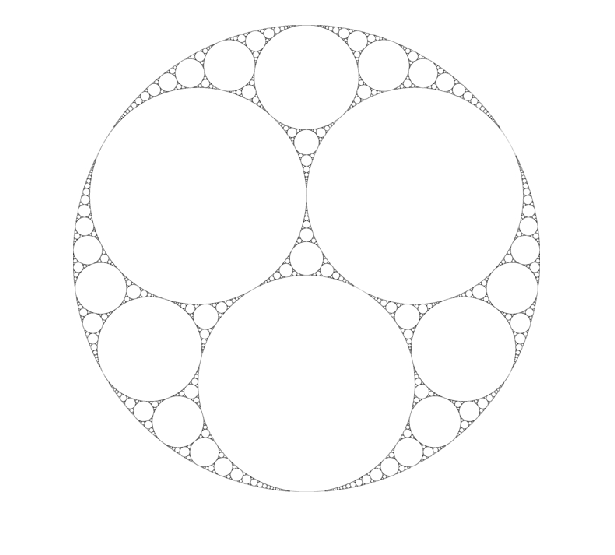

% imwrite(uint8(Verified_Image), 'test_img/verified.pgm');

[row, col] = size(Compressed_Image);
cell_rows = ones(row/8,1).*8;
cell_cols = ones(col/8,1).*8;
Compressed_Image = Compressed_Image/(2^3);
cell = mat2cell(Compressed_Image, cell_rows, cell_cols);
cell = cellfun(@(x) idct2(x), cell, 'un', 0);
Decompressed_Image = cell2mat(cell);
Decompressed_Image = abs(round(Decompressed_Image));
% Decompressed_Image = min(max(Decompressed_Image,255),0)
imshow((uint8(Decompressed_Image)));

imwrite(uint8(Decompressed_Image), 'test_img/Decompressed_Image.pgm', 'Encoding', 'ASCII');
